# Software documentation

ECSE507 Optimization Final Project

Student Name : Youjin Song  / Student ID : 261067354  / Date : March 18, 2022

## (a) Steepest Descent algorithm

The function `sgd2d` uses steepest gradient descent algorithm to find global minimum of given 2-dimensional function. It requires 4 input arguments (1 optional input argument included), and returns 3 output. 

### input

- f (function) : 2d function, with 2 input arguments.

- initial (vector) : starting point of searching algorithm. Should be (1,2) vector.

- plot (boolean) : If true, the algorithm shows 3d surface of the function and searching path after iteration.

- max_iter (int) : OPTIONAL input. Defines maximum iteration for SGD algorithm. If nothing is entered, max_iter becomes 10000 by default.

### output

- x (matrix) : (2,iter) matrix. 

- xhat (vector) : Location of local minimum found by the algorithm. It is (1,2) vector.

- fval (scalar) : Local minimum.

Following is an example to show how my algorithm works. I applied `sgd2d` function to a simple 2-d equation which has its minimum obviously at (2,3).

   9.2478e-05

number of total iteration: 211 
local minimum : -3.00 
location of local minimum : 2           3


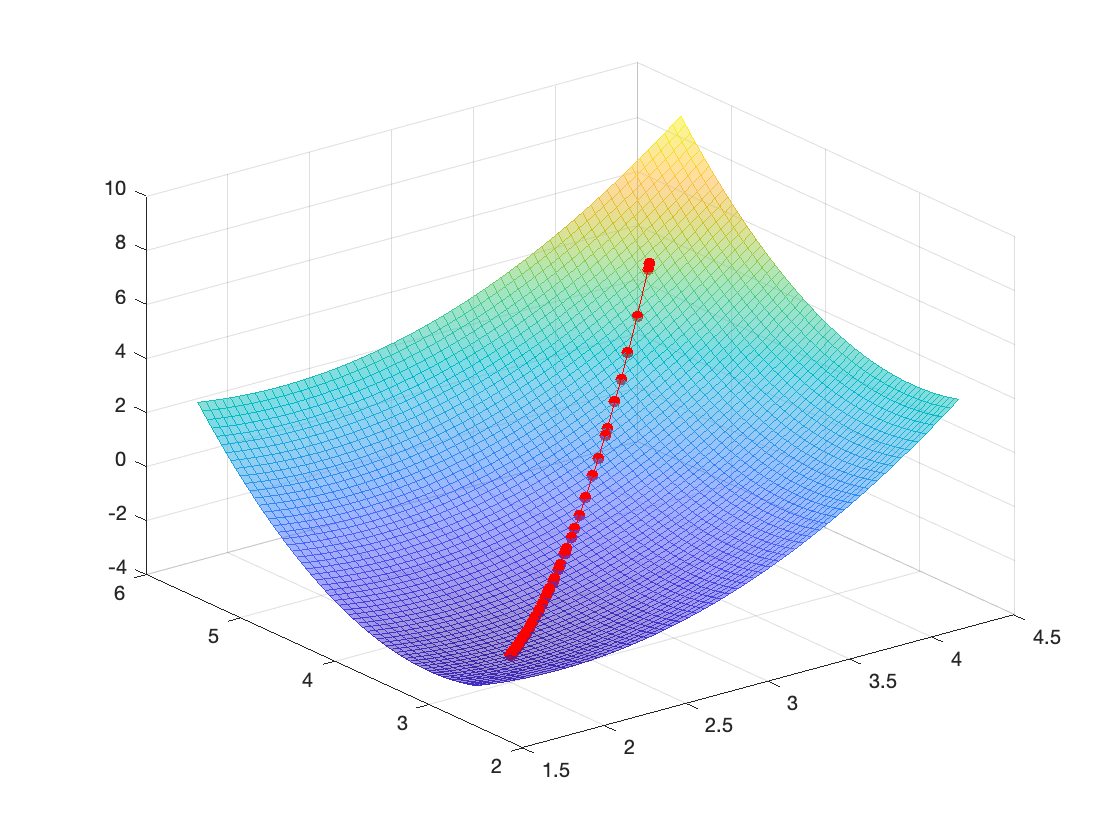

f = @(x,y) (x-2).^2+(y-3).^2 -3; % 2d function with 2 input argument 
[x,xhat,fval]=sgd2d(f,[4,5],true);

When compared to applying MATLAB Optimization Toolbox, it gives the same result.

F = @(x) f(x(1),x(2));
[xhat,fval]=fminsearch(F,[4,5],optimset('TolX',1e-10,'MaxFunEvals',10000,'MaxIter',10000));
fprintf('local minimum by MATLAB optimization Toolbox : %.2f \n',fval);

local minimum by MATLAB optimization Toolbox : -3.00 


disp(['location of local minimum by MATLAB optimization Toolbox : ', num2str(xhat)]);

location of local minimum by MATLAB optimization Toolbox : 2           3


The function `sgd_stdquad` uses steepest gradient descent algorithm to find global minimum of given standard quadratic function. It requires 4 input arguments, and returns 3 output. 

### input

- a (scarlar) : scalar coefficient 'a' for standard quadratic $\;a+b^T x+\frac{1}{2}x^T \textrm{Cx}$

- b (vector) : (n,1) vector 'b' for standard quadratic $\;a+b^T x+\frac{1}{2}x^T \textrm{Cx}$

- c (matrix) : (n,n) matrix 'C' for standard quadratic $\;a+b^T x+\frac{1}{2}x^T \textrm{Cx}$. C should be symmetric, positive definite.

- initial (vector) : starting point of searching algorithm. Should be in (n,1) vector

### output

- x (matrix) : (n,iter) matrix. 

- xhat (vector) : Location of local minimum found by the algorithm. It is (1,2) vector.

- fval (scalar) : Local minimum.

a=5;
b=[1 4 5 4 2 1]';
C=2*[9 1 7 5 4 7 ; 1 11 4 2 7 5 ;7 4 13 5 0 7;5 2 5 17 1 9 ;4 7 0 1 21 15;7 5 7 9 15 27];

if issymmetric(C) & all(eig(C))>0
    disp("This equation is standard quadratic"); % check whether C is symmetric, positive definite
end

This equation is standard quadratic



initial=randi([-10 10],6,1); % randomly choose a 6*1 vector to start with
[x,xhat,fval]=sgd_stdquad(a,b,C,initial);

   9.3555e-05

number of total iteration: 174 
local minimum : 3.65 
location of local minimum : 0.33657    0.056052    -0.43006      -0.192    -0.27132     0.21007


Minimization point of Standard Quatratic  $\;a+b^T x+\frac{1}{2}x^T \textrm{Cx}$ is known as $\widehat{x} =-C^{-1} b$. 

When compared this value to what I get from my sgd algorithm, 

disp(['location of local minimum(by property of standard quadratics): ',num2str((-inv(C)*b)')]);

location of local minimum(by property of standard quadratics): 0.33656     0.05604    -0.43004      -0.192    -0.27131     0.21007


the xhat is exactly the same. Therefore, my steepest Descent Algorithm is giving the right answer.

## (b) Apply Armijo step size rule selection to Steepest Descent algorithm

The function `sgd2d_armijo` uses steepest gradient descent algorithm to find global minimum of given 2-dimensional function, using Armijo step size rule for choosing step size each iteration. It requires 4 input arguments (1 optional input argument included), and returns 3 output. Input and output arguments are exactly same as (a) Steepest Descent algorithm.

Following is an example to show how my algorithm works. I applied `sgd2d` function to a simple 2-d equation which has its minimum obviously at (2,3).

   1.1523e-05

number of total iteration: 7 
local minimum : 0.00 
location of local minimum : 2           3


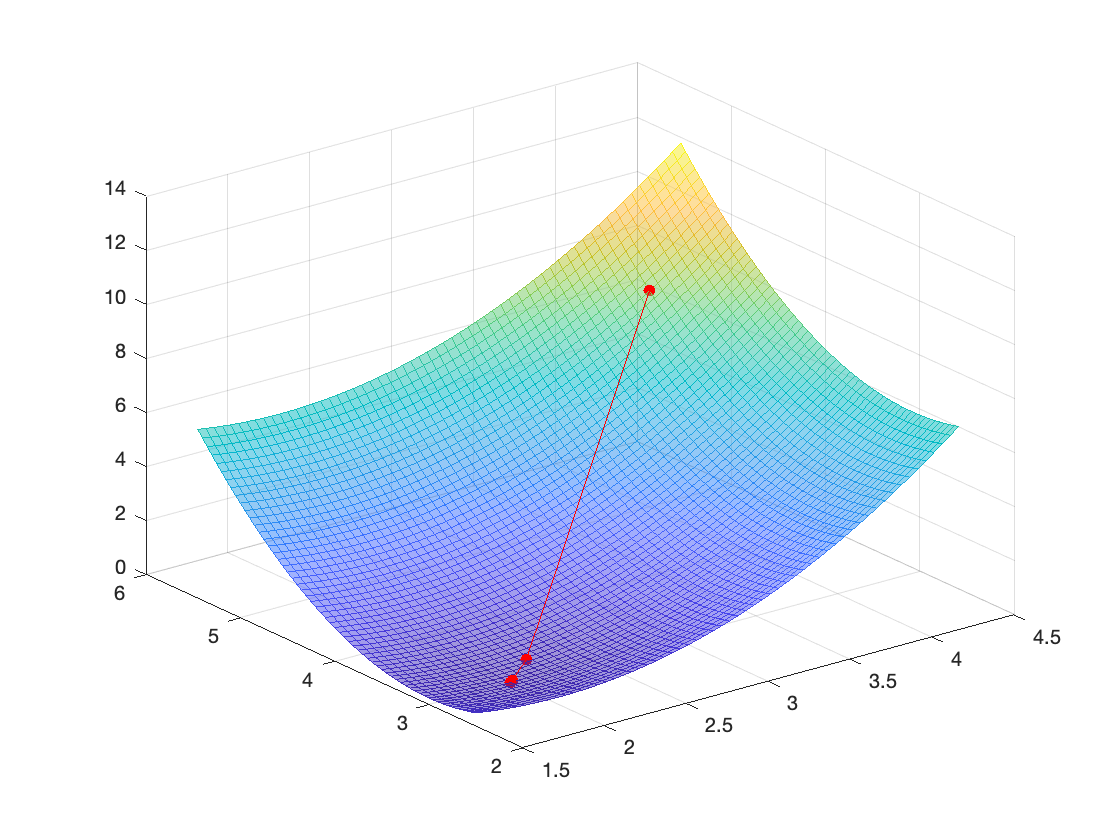

f = @(x,y) (x-2).^2+(y-3).^2; % 2d function with 2 input argument 
[x,xhat,fval]=sgd2d_armijo(f,[4,5],true);

When compared to applying MATLAB Optimization Toolbox, it gives the same result.

F = @(x) f(x(1),x(2));
[xhat,fval]=fminsearch(F,[4,5],optimset('TolX',1e-10,'MaxFunEvals',10000,'MaxIter',10000));
fprintf('local minimum by MATLAB optimization Toolbox : %.2f \n',fval);

local minimum by MATLAB optimization Toolbox : 0.00 


disp(['location of local minimum by MATLAB optimization Toolbox : ', num2str(xhat)]);

location of local minimum by MATLAB optimization Toolbox : 2           3


## (c) Conjugate Gradient algorithm

The function cg`2d` uses conjugate gradient descent algorithm to find global minimum of given 2-dimensional function. It requires 4 input arguments (1 optional input argument included), and returns 3 output. Input and output arguments are exactly same with `sgd2d` function.

### input

- f (function) : 2d function, with 2 input arguments.

- initial (vector) : starting point of searching algorithm. Should be (1,2) vector.

- plot (boolean) : If true, the algorithm shows 3d surface of the function and searching path after iteration.

- max_iter (int) : OPTIONAL input. Defines maximum iteration for SGD algorithm. If nothing is entered, max_iter becomes 10000 by default.

### output

- x (matrix) : (2,iter) matrix. 

- xhat (vector) : Location of local minimum found by the algorithm. It is (1,2) vector.

- fval (scalar) : Local minimum.

Following is an example to show how my algorithm works. I applied `sgd2d` function to a simple 2-d equation which has its minimum obviously at (2,3).

     0

number of total iteration: 58 
local minimum : -3.00 
location of local minimum : 2           3


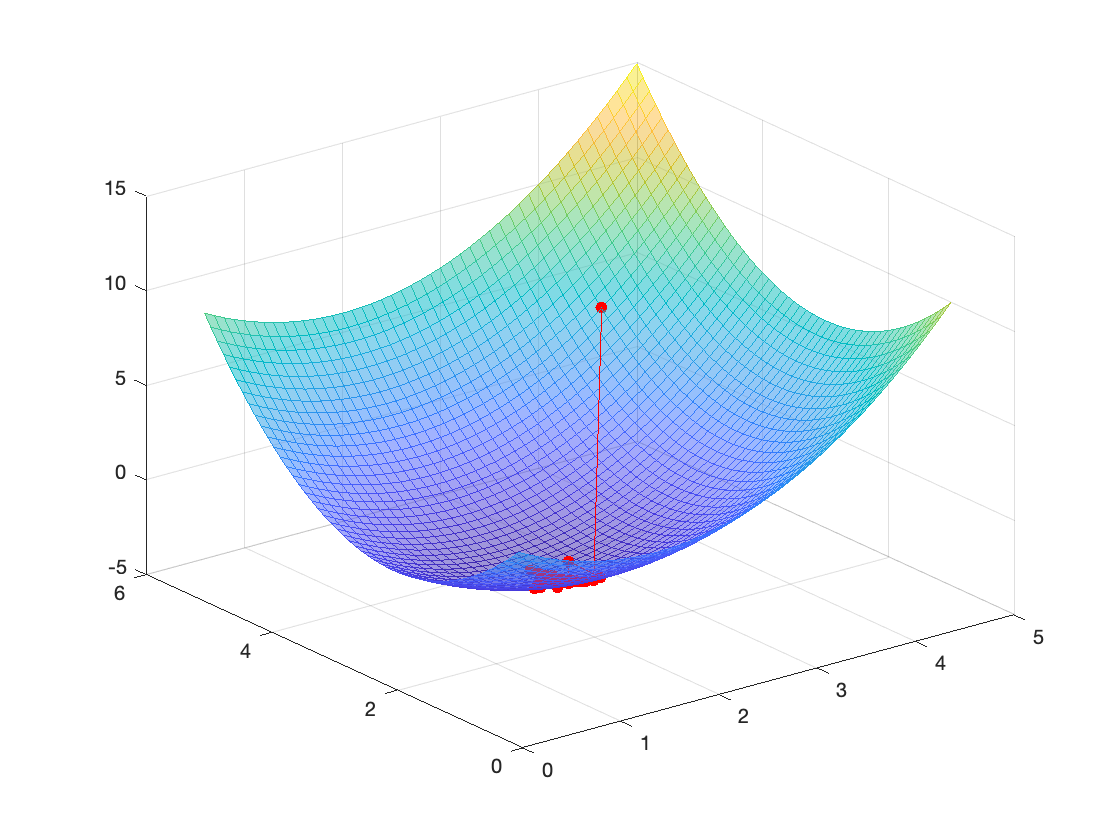

f = @(x,y) (x-2).^2+(y-3).^2 -3; % 2d function with 2 input argument 
[x,xhat,fval]=cg2d(f,[4,5],true);

When compared to applying MATLAB Optimization Toolbox, it gives the same result.

F = @(x) f(x(1),x(2));
[xhat,fval]=fminsearch(F,[4,5],optimset('TolX',1e-10,'MaxFunEvals',10000,'MaxIter',10000));
fprintf('local minimum by MATLAB optimization Toolbox : %.2f \n',fval);

local minimum by MATLAB optimization Toolbox : -3.00 


disp(['location of local minimum by MATLAB optimization Toolbox : ', num2str(xhat)]);

location of local minimum by MATLAB optimization Toolbox : 2           3


The function cg`_stdquad` uses steepest gradient descent algorithm to find global minimum of given standard quadratic function. It requires 4 input arguments, and returns 3 output. 

### input

- a (scarlar) : scalar coefficient 'a' for standard quadratic $\;a+b^T x+\frac{1}{2}x^T \textrm{Cx}$

- b (vector) : (n,1) vector 'b' for standard quadratic $\;a+b^T x+\frac{1}{2}x^T \textrm{Cx}$

- c (matrix) : (n,n) matrix 'C' for standard quadratic $\;a+b^T x+\frac{1}{2}x^T \textrm{Cx}$. C should be symmetric, positive definite.

- initial (vector) : starting point of searching algorithm. Should be in (n,1) vector

### output

- x (matrix) : (n,iter) matrix. 

- xhat (vector) : Location of local minimum found by the algorithm. It is (1,2) vector.

- fval (scalar) : Local minimum.

a=5;
b=[1 4 5 4 2 1]';
C=2*[9 1 7 5 4 7 ; 1 11 4 2 7 5 ;7 4 13 5 0 7;5 2 5 17 1 9 ;4 7 0 1 21 15;7 5 7 9 15 27];

if issymmetric(C) & all(eig(C))>0
    disp("This equation is standard quadratic"); % check whether C is symmetric, positive definite
end

This equation is standard quadratic



initial=randi([-10 10],6,1); % randomly choose a 6*1 vector to start with
[x,xhat,fval]=cg_stdquad(a,b,C,initial);

   9.1793e-05

number of total iteration: 209 
local minimum : 3.65 
location of local minimum : 0.33654    0.056031    -0.43003    -0.19199     -0.2713     0.21006


Minimization point of Standard Quatratic  $\;a+b^T x+\frac{1}{2}x^T \textrm{Cx}$ is known as $\widehat{x} =-C^{-1} b$. 

When compared this value to what I get from my sgd algorithm, 

disp(['location of local minimum(by property of standard quadratics): ',num2str((-inv(C)*b)')]);

location of local minimum(by property of standard quadratics): 0.33656     0.05604    -0.43004      -0.192    -0.27131     0.21007


the xhat is exactly the same. Therefore, my steepest Descent Algorithm is giving the right answer.

## (d) Secant algorithm

The function secant`2d` uses secant algorithm to find global minimum of given 2-dimensional function. It requires 4 input arguments (1 optional input argument included), and returns 3 output. Input and output arguments are exactly same with `sgd2d` function.

### input

- f (function) : 2d function, with 2 input arguments.

- initial (vector) : starting point of searching algorithm. Should be (1,2) vector.

- plot (boolean) : If true, the algorithm shows 3d surface of the function and searching path after iteration.

- max_iter (int) : OPTIONAL input. Defines maximum iteration for SGD algorithm. If nothing is entered, max_iter becomes 10000 by default.

### output

- x (matrix) : (2,iter) matrix. 

- xhat (vector) : Location of local minimum found by the algorithm. It is (1,2) vector.

- fval (scalar) : Local minimum.

Following is an example to show how my algorithm works. I applied `secant2d` function to a simple 2-d equation which has its minimum obviously at (2,3).

   2.5121e-08

number of total iteration: 2 
local minimum : -3.00 
location of local minimum : 2           3


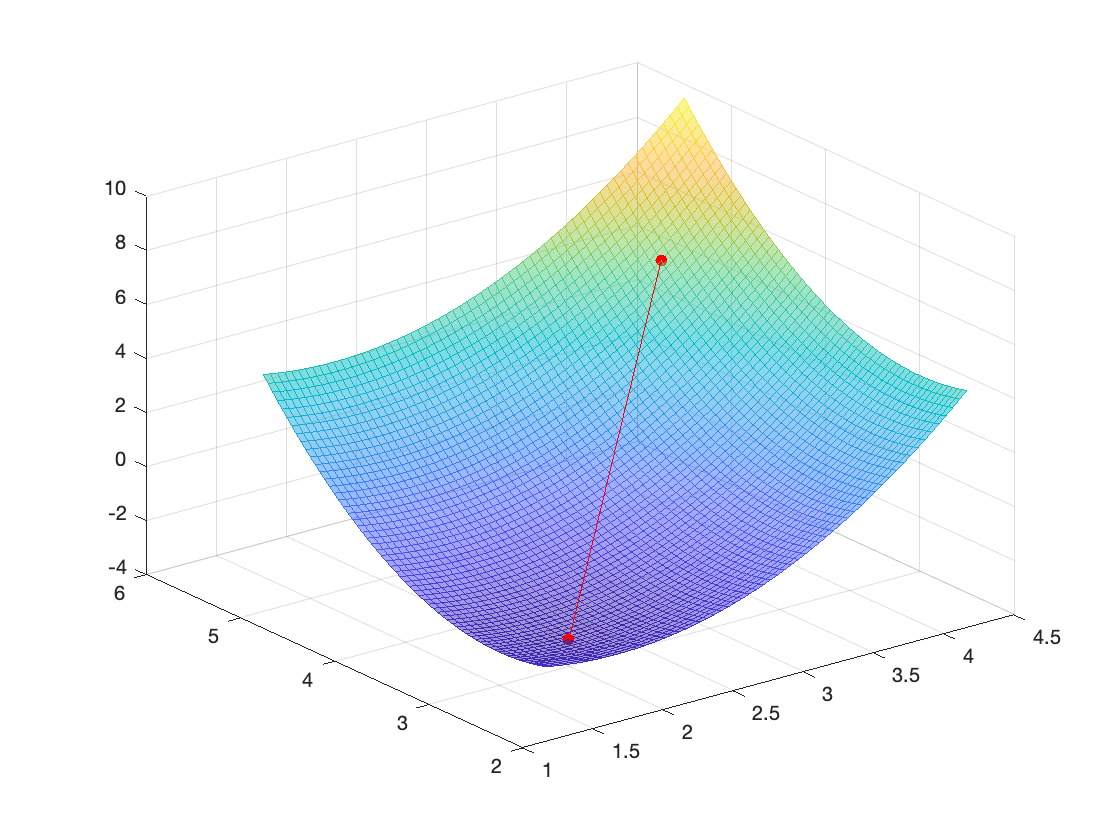

f = @(x,y) (x-2).^2+(y-3).^2 -3; % 2d function with 2 input argument 
[x,xhat,fval]=secant2d(f,[4,5],true);

When compared to applying MATLAB Optimization Toolbox, it gives the same result.

F = @(x) f(x(1),x(2));
[xhat,fval]=fminsearch(F,[4,5],optimset('TolX',1e-10,'MaxFunEvals',10000,'MaxIter',10000));
fprintf('local minimum by MATLAB optimization Toolbox : %.2f \n',fval);

local minimum by MATLAB optimization Toolbox : -3.00 


disp(['location of local minimum by MATLAB optimization Toolbox : ', num2str(xhat)]);

location of local minimum by MATLAB optimization Toolbox : 2           3


The function secant`_stdquad` uses steepest gradient descent algorithm to find global minimum of given standard quadratic function. It requires 4 input arguments, and returns 3 output. 

### input

- a (scarlar) : scalar coefficient 'a' for standard quadratic $\;a+b^T x+\frac{1}{2}x^T \textrm{Cx}$

- b (vector) : (n,1) vector 'b' for standard quadratic $\;a+b^T x+\frac{1}{2}x^T \textrm{Cx}$

- c (matrix) : (n,n) matrix 'C' for standard quadratic $\;a+b^T x+\frac{1}{2}x^T \textrm{Cx}$. C should be symmetric, positive definite.

- initial (vector) : starting point of searching algorithm. Should be in (n,1) vector

### output

- x (matrix) : (n,iter) matrix. 

- xhat (vector) : Location of local minimum found by the algorithm. It is (1,2) vector.

- fval (scalar) : Local minimum.

a=5;
b=[1 4 5 4 2 1]';
C=2*[9 1 7 5 4 7 ; 1 11 4 2 7 5 ;7 4 13 5 0 7;5 2 5 17 1 9 ;4 7 0 1 21 15;7 5 7 9 15 27];

if issymmetric(C) & all(eig(C))>0
    disp("This equation is standard quadratic"); % check whether C is symmetric, positive definite
end

This equation is standard quadratic



initial=randi([-10 10],6,1); % randomly choose a 6*1 vector to start with
[x,xhat,fval]=secant_stdquad(a,b,C,initial);

   9.8402e-05

number of total iteration: 642 
local minimum : 3.65 
location of local minimum : 0.33656    0.056041    -0.43004      -0.192    -0.27131     0.21007


Minimization point of Standard Quatratic  $\;a+b^T x+\frac{1}{2}x^T \textrm{Cx}$ is known as $\widehat{x} =-C^{-1} b$. 

When compared this value to what I get from my sgd algorithm, 

disp(['location of local minimum(by property of standard quadratics): ',num2str((-inv(C)*b)')]);

location of local minimum(by property of standard quadratics): 0.33656     0.05604    -0.43004      -0.192    -0.27131     0.21007


the xhat is exactly the same. Therefore, my steepest Descent Algorithm is giving the right answer.

## (e) Finite difference approximation

The function myGrad computes gradient of a function on a certain point. This function is utilized in above (a)~(d) algorithms for getting gradients. It requires 2 input arguments, and returns 1 output. 

### input

- f (function) : any function, with 1 input argument.

- x (vector) : point on which the gradient would be calculated. It should be in either (n,1) or (1,n) vector format.

### output

- gradient (vector) : gradient calculated of the point x on the function f. It has the same size of input vector x.

To check whether our algorithm works well, I applied `myGrad` function to a simple 2-d equation $f\left(x,y\right)=3{\left(x-2\right)}^2 +{\left(y-3\right)}^2$ . 

This function has gradient :  $\nabla f\left(x,y\right)=<6x-12\;,2y-6>$


$$\textrm{if}\;x=3,y=4,\textrm{gradient}\;\textrm{from}\;\textrm{this}\;\textrm{point}\;\textrm{is}\;<6\;,2>$$



$$\textrm{if}\;x=2,y=3,\textrm{gradient}\;\textrm{from}\;\textrm{this}\;\textrm{point}\;\textrm{is}\;<0,\;0>$$


f = @(x)  3*(x(1)-2).^2+(x(2)-3).^2;  % 2d function with 1 input argument 
myGrad(f,[3,4])

ans =     6.0000    2.0000


myGrad(f,[2,3])

ans = 	1.0e+-6 *

    0.3000    0.1000


This algorithm also works in higher dimension function, like standard quadratics below.

a=5;
b=[1 4 5 4 2 1]';
C=2*[9 1 7 5 4 7 ; 1 11 4 2 7 5 ;7 4 13 5 0 7;5 2 5 17 1 9 ;4 7 0 1 21 15;7 5 7 9 15 27];
f=@(x) a+b'*x+0.5*x'*C*x;
x=[1,1,2,3,1,4]';
myGrad(f,x)

ans =   143.0000
  110.0000
  165.0000
  214.0000
  192.0000
  353.0000


When compared to known graident for standard quadratic b+Cx, 

b+C*x

ans =    143
   110
   165
   214
   192
   353


The `myGrad` function is calculating the gradient of a certain point correctly.

## (f) penalty and barrier function algorithm for constrained optimization problem

The function `penalty_barrier2d` computes minimum value and its corresponding location using either penalty function or barrier function. It requires 6 input arguments, and returns 3 output. 

### input

- mode (string) : should be either "penalty" or "barrier". If one of the constraints include an equality constraint, it should only be "**penalty**".

- f0 (function) : Objective function. Should be 2d function with 2 input arguments.

- h1 (function) : The inequality constraint of the problem. h1 should be a form of 2d function with 2 input arguments, and 'greater or equal to zero' part of the Inequality. For example, if the constraint is $g\left(x\right)\le 3$, this inequality can be also written as $3-g\left(x\right)\ge 0$. Therefore, h should be $h\left(x\right)=3-g\left(x\right)$ . 

- h2 (function) : The equality OR ineqaulity constraint of the problem. It should be a form of 2d function with 2 input arguments. If the second constraint is also Inequality, it should follow the format of former input h1. If it is eqaulity, h2 should be a form of 2d function with 2 input arguments, and 'equals to zero' part of the equality. For example, if the constraint is $g\left(x\right)=6$, this inequality can be also written as $g\left(x\right)-6=0$. Therefore, h should be $h\left(x\right)=g\left(x\right)-6$  here . 

- E (boolean) : If true, the problem has 1 equality constraint and 1 inequality constraint. If false, the problem only has 2 inequality constraints. E should be only false to use **barrier method**.

- initial (vector) : starting point of searching algorithm. Should be (1,2) vector. Note that when using **barrier** method, the initial vector should satisy two inequality constraints.

### output

- x (matrix) : (2,iter) matrix. 

- xhat (vector) : Location of local minimum found by the algorithm. It is (1,2) vector.

- fval (scalar) : Local minimum.

Following is an example to show how my algorithm works. The equation is from PART2 (3).

    minimize $V\left(x,y\right)=\ln \left(x\right)-y;\;$$x,y\in R$

    subject to : $\begin{array}{l}
h_1 \left(x,y\right)=x-1\ge 0\;\\
\;h_2 \left(x,y\right)=x^2 +y^2 -4=0
\end{array}$

mode = "penalty";
f0 = @(x,y) log(x)-y;
h1 = @(x,y) x-1; %>=0
h2 = @(x,y) x.^2+y.^2-4; %==0
initial = [3,3];
E=true;

[x,xhat,fval]=penalty_barrier2d(mode,f0,h1,h2,E,initial);
disp([num2str(xhat),'  fval:',num2str(fval)]);

0.99992      1.7321  fval:-1.7322


[x,xhat,fval]=penalty_barrier2d("barrier",f0,h1,h2,E,initial);

barrier method doesn't allow equality constraint


Substituing "panelty" to "barrier" shows error message since the given problem has equality constraint.

Try for different problem with only Inequality constraints exist. The equation is from PART2 (1).

    minimize $V\left(x,y\right)=-\textrm{xy};\;$$x,y\in R$

    subject to : $\begin{array}{l}
h_1 \left(x,y\right)=-x-y^2 +1\ge 0\;\\
\;h_2 \left(x,y\right)=x+y\ge 0
\end{array}$

f0 = @(x,y) -x.*y;
h1 = @(x,y) -x-y.^2 +1 ; %>=0
h2 = @(x,y) x+y; %>=0
initial = [2,-1];
E=0;
[x,xhat,fval]=penalty_barrier2d("barrier",f0,h1,h2,E,initial);

Initial point should be in feasible area to use barrier function


Since initial point (2,-1) doesn't satisfies two ineqaulity constraints $h_1 \left(x,y\right)\;\textrm{and}\;h_2 \left(x,y\right)$, we can't apply barrier method.

Changing initial point to (-0.5,1) can properly solve the problem by barrier method.

initial = [-0.5,1];
[x,xhat,fval]=penalty_barrier2d("barrier",f0,h1,h2,E,initial);
disp([num2str(xhat),'  fval:',num2str(fval)]);

0.64795     0.59334  fval:-0.38445
